## Assignment 7

### Part one

Task 1-2

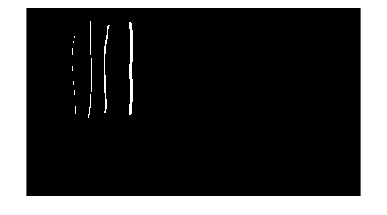

horizontals1 = showImage("hor_lines_bw.bmp");

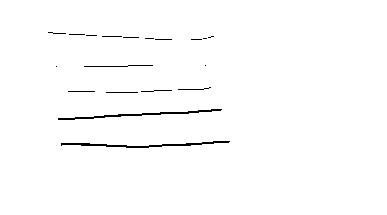

horizontals2 = showImage("hor_lines.bmp");

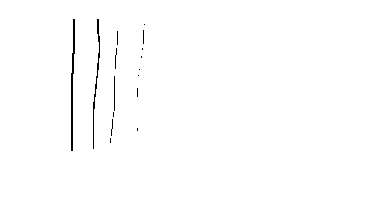

verticals1 = showImage("ver_lines.bmp");

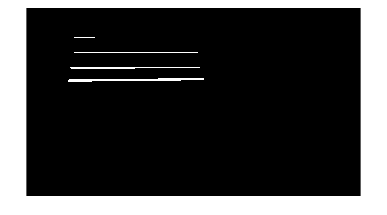

verticals2 = showImage("ver_lines_bw.bmp");

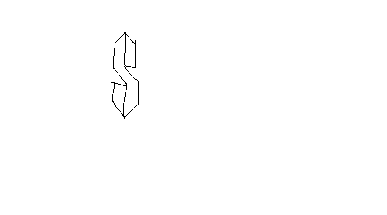

dollasign = showImage("dollasign.bmp");

Task 3

Nfft = 1024;
%xfreqs = linspace(-0.5, 0.5, Nfft+1)*(1/deltaX); xfreqs(end) = [];
%yfreqs = linspace(-0.5, 0.5, Nfft+1)*(1/deltaY); yfreqs(end) = [];

hor1fft = fft2d(horizontals1);

Not enough input arguments.

Error in ass7_code>fft2d (line 28)
    res = fft2(image,nfft);

hor2fft = fft2d(horizontals2);
ver1fft = fft2d(verticals1);
ver2fft = fft2d(verticals2);


hor1fft_plot = fftimage(hor1fft);
hor2fft_plot = fftimage(hor2fft);
ver1fft_plot = fftimage(ver1fft);
ver2fft_plot = fftimage(ver2fft);

function image = showImage(path)
    image = imread(path);
    figure();
    imshow(double(image));
    colormap(gray(255));
end

function res = fft2d(image,nfft)
    res = fft2(image,nfft);
    res = fftshift(res);
end
function im = fftimage(res)
    figure();
    im = imshow(mag2db(abs(res)));

end
